# Workflow Cluster Determination

This workflow show how to determine and look for Clusters in your dataset. 

All of the codes are based on the use of Coronoi cells. In the paper "Detecting and extracting clusters in atom probe data: A simple, automated method using Voronoi cells" P.Felfer, A.V. Ceguerra, S.P. Ringer, J.M. Cairney Utramicroscopy 150 (2015) 30-36

A decomposed pos file is a prerequisite.

## Determine the clusters

The clusterDetermination function colculates the pass, Nmin, clusterCutoff and a pos file with the clustered Atoms. It calculates the voronoi Volume in combination with the delaunay triangulation. the Kolmogorov - Smirnov test is also performed.

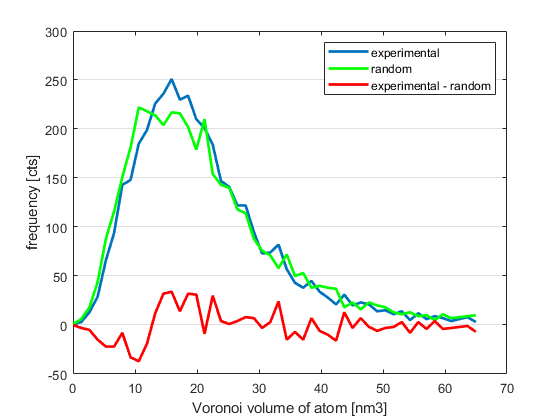

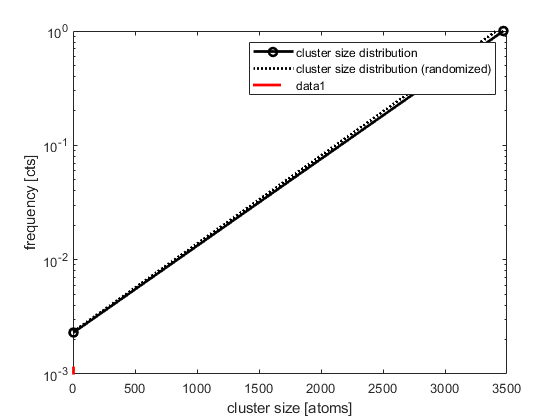

clusterPos = pos(pos.ion == 'Cr',:);
[clusterParameter, clusteredAtoms, clusterPosVol, randomVolumes]= clusterDetermination(clusterPos,pos);

adjust the axes

ax = gca;

Index exceeds the number of array elements (2670).

Error in tabular/dotParenReference (line 114)
        b = b(rowIndices);

ax.XScale = 'log';

## Additional functions for more detail 

### Voronoi Volume analysis

with this function, the voronoi volume is calculated for a given data set 

[numClustered, clusterCutoff, histCounts, experimentalVolumes, randomVolumes] = voronoiVolumeAnalysis(clusterPos, pos);

### clusterIdentification

clusterIdentification calculates the number of clusters and their corresponding cluster Index after Voronoi Tesselation and Dealaunay triangulation

Dataset:

volThreshORpos = clusterCutoff; % or pos
[clusterIdx, numClusters] = clusterIdentification(clusterPos,volThreshORpos,experimentalVolumes.expVol);

random Dataset:

[randomClusterIdx, randomNumClusters] = clusterIdentification(randomVolumes,volThreshORpos,randVolumes.randVol);

### Analyse the cluster size

at Nmin atoms, it is a cluster

clusterSizes = histcounts(clusterIdx, numClusters);
randomClusterSizes = histcounts(randomClusterIdx, randomNumClusters);
Nmin = clusterSizeAnalyse(expClusterSizes,ranClusterSizes);